# Cuadraturi de tip Gauss

## Formule Gauss-Legendre

Să se calculeze integralele $\int_{-1}^1 \sin x^2 \textrm{dx}$ și $\int_{-1}^1 \cos x^2 \textrm{dx}$ cu precizia $\varepsilon=10^{-7$ folosind o cuadratură gaussiană. Câte noduri sunt necesare?

Vom folosi o formulă de tip Gauss-Legendre

f1=@(x) sin(x.^2);
f2=@(x) cos(x.^2);
tol=1e-7;
n0=5;
[g_n1,g_c1]=Gauss_Legendre(n0);
v1(1)=vquad(g_n1,g_c1,f1);
v2(1)=vquad(g_n1,g_c1,f2);
k=1;
for n=n0+1:4*n0
    [gn,gc]=Gauss_Legendre(n);
    k=k+1;
    v1(k)=vquad(gn,gc,f1);
    if abs(v1(k)-v1(k-1)) < tol
        disp([gn,gc'])
        fprintf('I1(%2d)=%12.8f\n',n,v1(k))
        break;
    end
end

   -0.9603    0.1012
   -0.7967    0.2224
   -0.5255    0.3137
   -0.1834    0.3627
    0.1834    0.3627
    0.5255    0.3137
    0.7967    0.2224
    0.9603    0.1012



I1( 8)=  0.62053660


k=1;
for n=n0+1:4*n0
    [gn,gc]=Gauss_Legendre(n);
    k=k+1;
    v2(k)=vquad(gn,gc,f2);
    if abs(v2(k)-v2(k-1)) < tol
        fprintf('I2(%2d)=%12.8f\n',n,v2(k))
        break;
    end
end

I2( 8)=  1.80904847


Verificare simbolică

syms t rest f(t) xi
vpa(int(sin(t^2),t,-1,1))

$$ans = 0.62053660344676220361630484633079$$

vpa(int(cos(t^2),t,-1,1))

$$ans = 1.8090484758005441629495767336651$$

Verificare cu formula restului

po=legendreP(n,t);
c=coeffs(po,'All');
po=po/c(1)

$$po = \frac{7}{1287}-\frac{28\,t^{2}}{143}+\frac{14\,t^{4}}{13}-\frac{28\,t^{6}}{15}+t^{8}$$

rest=1/factorial(2*n)*int(po^2,t,-1,1)*subs(diff(f(t),t,n),t,xi);
[rest,vpa(rest)]

$$ans = \left(\begin{array}{cc} \frac{7573384136472607\,\frac{\partial^{8}}{\partial \xi^{8}}f\left(\xi \right)}{3404126326545748309514119859404800} & 0.000000000000000002224765889977270125691636407827\,\frac{\partial^{8}}{\partial \xi^{8}}f\left(\xi \right) \end{array}\right)$$

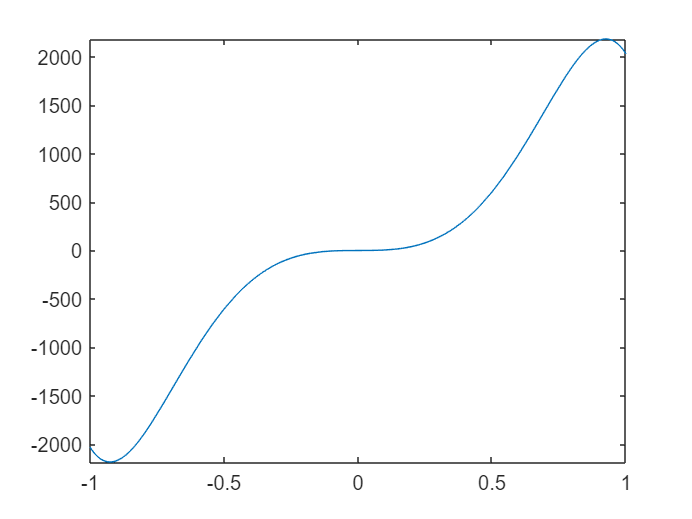

fplot(diff(sin(t^2),t,7),[-1,1])

## Formule Gauss-Cebîșev #1

Să se aproximeze 


$$\int_{-1}^1 \frac{\cos \left(x\right)}{\sqrt{1-x^2 }}\textrm{dx}$$


folosind o formulă gaussiană cu 10 noduri. Care este eroarea de aproximare?

Formula va fi de tip Gauss-Cebîșev de speța I. Calculăm nodurile și coeficienții. Coeficienții sunt egali cu $\frac{\pi}{10}$, iar nodurile sunt rădăcinile polinomului Cebîșev de speța 1 de grad 10, $T_n(x)=\cos(10\arccos x)$, adică $\cos\frac{(2k-1)\pi}{2n+2},\ k=1..11,\ n=10$.

[g_n,g_c]=Gauss_Cheb1(10);
disp([g_n,g_c'])

    0.9877    0.3142
    0.8910    0.3142
    0.7071    0.3142
    0.4540    0.3142
    0.1564    0.3142
   -0.1564    0.3142
   -0.4540    0.3142
   -0.7071    0.3142
   -0.8910    0.3142
   -0.9877    0.3142



Valoarea aproximativă a integralei este

format long
vI=vquad(g_n,g_c,@cos)

vI =    2.403939430634413


Deoarece $\left|\cos^{\left(n\right)} x\right|\le 1$, restul va fi mai mic decât

po=chebyshevT(10,t)/2^(9)

$$po = -\frac{1}{512}+\frac{25\,t^{2}}{256}-\frac{25\,t^{4}}{32}+\frac{35\,t^{6}}{16}-\frac{5\,t^{8}}{2}+t^{10}$$

rest=1/factorial(20)*int(po^2/sqrt(1-t^2),t,-1,1)

$$rest = \frac{8536795713241637\,\pi }{10889035741470030830827987437816582766592}$$

double(vpa(rest))

ans =      2.462948541511184e-24


Putem face și o verificare simbolică. Valoarea exactă a integralei este

ve=int(cos(t)/sqrt(1-t^2),t,-1,1)

$$ve = \pi \,J_{0}\left(1\right)$$

Diferența dintre valoarea exactă și cea calculată:

double(ve)

ans =    2.403939430634413


abs(double(ve)-vI)

ans =      4.440892098500626e-16


Explicați de ce este mai mare decât restul.

## Formule Gauss-Cebîșev #2

Să se aproximeze 


$$\int_{-1}^1 \sqrt{1-x^2 }\cos \left(x\right)\textrm{dx}$$


folosind o formulă gaussiană cu 5 noduri. Care este eroarea de aproximare?

Formula va fi de tip Gauss-Cebîșev de speța II. Calculăm nodurile și coeficienții. Nodurile sunt rădăcinile polinomului Cebîșev de speța II de grad 5, $U_{n}(x)=\frac{\sin(n+1)\arccos(x)}{\sqrt{1-x^2}}$.

[g_n,g_c]=Gauss_Cheb2(5);
disp([g_n,g_c'])

  -0.866025403784439   0.130899693899575
  -0.500000000000000   0.392699081698724
  -0.000000000000000   0.523598775598299
   0.500000000000000   0.392699081698724
   0.866025403784439   0.130899693899575



Valoarea aproximativă a integralei este

format long
vI=vquad(g_n,g_c,@cos)

vI =    1.382459687798957


Deoarece $\left|\cos^{\left(n\right)} x\right|\le 1$, restul va fi mai mic decât

po=chebyshevU(5,t)/2^5

$$po = \frac{3\,t}{16}-t^{3}+t^{5}$$

rest=1/factorial(10)*int(po^2*sqrt(1-t^2),t,-1,1)

$$rest = \frac{1301357606610903\,\pi }{9671406556917033397649408}$$

double(vpa(rest))

ans =      4.227239825522600e-10


Putem face și o verificare simbolică. Valoarea exactă a integralei este

ve=int(cos(t)*sqrt(1-t^2),t,-1,1)

$$ve = \pi \,J_{1}\left(1\right)$$

Diferența dintre valoarea exactă și cea calculată:

double(ve)

ans =    1.382459687384169


abs(double(ve)-vI)

ans =      4.147882037841555e-10


Ea este în concordanță cu restul.

## Formule Gauss-Laguerre

Să se aproximeze 


$$\int_0^{\infty } e^{-x} \sin \left(x\right)\textrm{dx}$$


folosind o formulă gaussiană cu 6 noduri. Care este eroarea de aproximare?

Formula este de tip Gauss-Laguerre.

Nodurile formulei vor fi rădăcinile polinomului Laguerre de grad 6, ortogonal pe $(0,\infty)$ în raport cu ponderea $w(x)=e^{-x}$.

po=laguerreL(6,0,t)

$$po = 1-6\,t+\frac{15\,t^{2}}{2}-\frac{10\,t^{3}}{3}+\frac{5\,t^{4}}{8}-\frac{t^{5}}{20}+\frac{t^{6}}{720}$$

c=coeffs(po,'All');
po=po/c(1)

$$po = 720-4320\,t+5400\,t^{2}-2400\,t^{3}+450\,t^{4}-36\,t^{5}+t^{6}$$

Coeficienții și nodurile se obțin astfel

[g_n,g_c]=Gauss_Laguerre(6);
disp([g_n,g_c'])

   0.222846604179261   0.458964673949964
   1.188932101672623   0.417000830772121
   2.992736326059315   0.113373382074045
   5.775143569104513   0.010399197453149
   9.837467418382587   0.000261017202815
  15.982873980601699   0.000000898547906



Valoarea integralei

format long
vI=vquad(g_n,g_c,@sin)

vI =    0.500049474797675


Deoarece $\left|\sin^{\left(n\right)} x\right|\le 1$, restul va fi mai mic decât

rest=1/factorial(12)*int(po^2*exp(-t),t,0,Inf)

$$rest = \frac{1277696559217977675}{1180591620717411303424}$$

double(vpa(rest))

ans =    0.001082251082251


Putem face și o verificare simbolică. Valoarea exactă a integralei este

ve=int(sin(t)*exp(-t),t,0,Inf)

$$ve = \frac{1}{2}$$

Diferența dintre valoarea exactă și cea calculată:

double(ve)

ans =    0.500000000000000


abs(double(ve)-vI)

ans =      4.947479767514196e-05


Ea este în concordanță cu restul.

## Formule Gauss-Hermite

Să se aproximeze


$$\int_{-\infty }^{\infty } e^{-x^2 } \left(\cos \left(x\right)+\sin \left(x\right)\right)\textrm{dx}$$


cu 8 zecimale exacte.

Formula este de tip Gauss-Hermite. Vom obține numărul de noduri din formula restului. Derivata de orice ordin a lui $\cos x +\sin x$ este $\leq \sqrt{2}$

syms R
for n=5:15
    po=hermiteH(n,t);
    c=coeffs(po,'All');
    po=po/c(1);
    R=int(po^2*exp(-t^2),t,-Inf,Inf)/factorial(2*n);
    if double(R) < 1e-8/sqrt(2)
        po, R 
        disp([double(R),n])
        break
    end
end

$$po = -\frac{105\,t}{8}+\frac{105\,t^{3}}{4}-\frac{21\,t^{5}}{2}+t^{7}$$

$$R = \frac{\sqrt{\pi }}{2214051840}$$

   0.000000000800548   7.000000000000000



Calculăm nodurile, coeficienții și valoarea aproximativă a integralei

f=@(x) sin(x)+cos(x);
[g_n,g_c]=Gauss_Hermite(n);
disp([g_n,g_c'])

  -2.651961356835232   0.000971781245100
  -1.673551628767471   0.054515582819127
  -0.816287882858965   0.425607252610128
   0.000000000000000   0.810264617556807
   0.816287882858964   0.425607252610128
   1.673551628767471   0.054515582819127
   2.651961356835233   0.000971781245100



vI=vquad(g_n,g_c,f)

vI =    1.380388447754078


Valoarea exactă a integralei

ve=int(exp(-t^2)*(cos(t)+sin(t)),t,-Inf,Inf)

$$ve = \sqrt{\pi }\,{\mathrm{e}}^{-\frac{1}{4}}$$

abs(double(ve)-vI)

ans =      7.109348665323978e-10


este în concordanță cu restul.

## Formule Gauss-Jacobi

Să se aproximeze


$$\int_{-1}^1 \sqrt{\frac{1-x}{1+x}}\frac{x^2 }{1+x^2 }\textrm{dx}$$


folosind o formulă gaussiană cu 8 noduri. Care este eroarea de aproximare?

Formula este de tip Gauss-Jacobi.

Nodurile formulei vor fi rădăcinile polinomului Jacobi de grad 8, ortogonal pe $[-1,1]$ în raport cu ponderea $w(x)=\sqrt{\frac{1-x}{1+x}}$.

po=jacobiP(8,1/2,-1/2,t);
c=coeffs(po,'All');
po=po/c(1)

$$po = \frac{1}{256}-\frac{t}{32}-\frac{5\,t^{2}}{32}+\frac{5\,t^{3}}{16}+\frac{15\,t^{4}}{16}-\frac{3\,t^{5}}{4}-\frac{7\,t^{6}}{4}+\frac{t^{7}}{2}+t^{8}$$

Coeficienții și nodurile se obțin astfel

[g_n,g_c]=Gauss_Jacobimodificat(8,1/2,-1/2);
disp([g_n,g_c'])

  -0.982973099683902   0.732905143792132
  -0.850217135729614   0.683838654253425
  -0.602634636379256   0.592332376475014
  -0.273662990072083   0.470744740324667
   0.092268359463302   0.335496829804836
   0.445738355776538   0.204854624665768
   0.739008917220659   0.096462078624944
   0.932472229404356   0.024958205649009



Valoarea integralei

f=@(x) x.^2./(1+x.^2);
format long
vI=vquad(g_n,g_c,f)

vI =    0.920152566416141


Valoarea exactă a integralei

ve=int(sqrt((1-t)/(1+t))*t^2/(1+t^2),t,-1,1)

$$ve = -\frac{\pi \,\left(\sqrt{2}-2\right)}{2}$$

abs(double(ve)-vI)

ans =      1.381905530672967e-06


este în concordanță cu valoarea calculată.

Restul va fi

syms f(t) F(t)
f(t)=t^2/(1+t^2);
R=int(po^2*sqrt((1-t)/(1+t)),t,-1,1)/factorial(16)*subs(diff(F(t),t,16),t,xi)

$$R = \frac{\pi \,\frac{\partial^{16}}{\partial \xi^{16}}F\left(\xi \right)}{1371195958099968000}$$

double(int(po^2*sqrt((1-t)/(1+t)),t,-1,1)/factorial(16))

ans =      2.291133251255364e-18


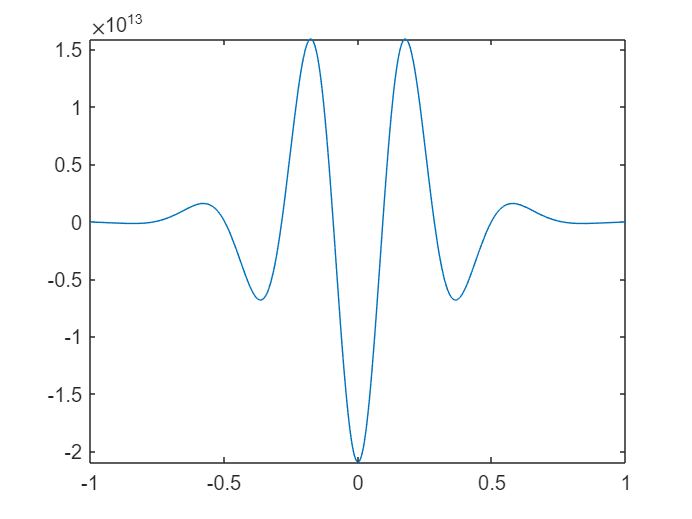

fplot(diff(f(t),t,16),[-1,1])

Valoarea aproximativă a restului va fi

R=int(po^2*sqrt((1-t)/(1+t)),t,-1,1)/factorial(16)*subs(diff(f(t),t,16),t,0)

$$R = -\frac{\pi }{65536}$$

double(R)

ans =     -4.793689962142629e-05
